# Example: COVID-2019 data for an entire Country

I am taking some data from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 14-Feb-2021


Location = 'Germany';
% Version 4.8 and above have an additional table conditions (thank to Aleks Czernicki)
% For more details, see: https://github.com/ECheynet/SEIR/pull/12
try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1 & (tableRecovered.ProvinceState.ismissing()==1))
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1 & (tableConfirmed.ProvinceState.ismissing()==1))
    indD = find(contains(tableDeaths.CountryRegion,Location)==1 & (tableDeaths.ProvinceState.ismissing()==1))
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));    
end

indR = 120

indC = 135

indD = 135


disp(tableRecovered(indR,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

      <missing>        "Germany"  



disp(tableConfirmed(indC,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

      <missing>        "Germany"  



disp(tableDeaths(indD,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

      <missing>        "Germany"  




indR = indR(1);
indD = indD(1);
indC = indC(1);

Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases

## Choose Initial and final time

tStart = datetime(2020,10,01);
tEnd = datetime(2021,02,24);
indT = find(time>=tStart & time <=tEnd);
Recovered=Recovered(indT);
Deaths = Deaths(indT);
time = time(indT);
Confirmed = Confirmed(indT);

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end

Npop= 0.3e9; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.1; % rate at which infectious people enter in quarantine
lambda_guess = [0.01,0.001,10]; % recovery rate
kappa_guess = [0.001,0.001,10]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
I0 = 0.3*Q0; % Initial number of infectious cases. Unknown but unlikely to be zero.
E0 = 0.3*Q0; % Initial number of exposed cases. Unknown but unlikely to be zero.
R0 = Recovered(1);
D0 = Deaths(1);

Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         11     5.39514e+14                      5.42e+16
     1         22     6.72299e+13       0.377972       7.75e+15      
     2         33     1.19741e+13        1.73694       1.02e+15      
     3         44      3.8193e+12       0.178299        1.2e+14      
     4         55     3.78764e+12        2.77449       2.75e+14      
     5         66     6.11955e+11       0.693622       4.78e+13      
     6         77     5.09518e+11        1.38724       2.89e+12      
     7         88     4.19338e+11        2.77449       2.26e+13      
     8         99     3.98667e+11       0.696764       6.02e+13      
     9        110     3.48018e+11    0.000655603        2.7e+12      
    10        121     3.47745e+11       0.174191       1.23e+11      
    11        132     3.47745e+11       0.348382       1.23e+11      
    12        143     3.46763e+1

## Simulate the epidemy outbreak based on the fitted parameters

dt = 1/24; % time step
time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end)+datenum(10), 'Locale', 'en_US');
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,...
    Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);

## Display the fitted and measured death and recovery rates

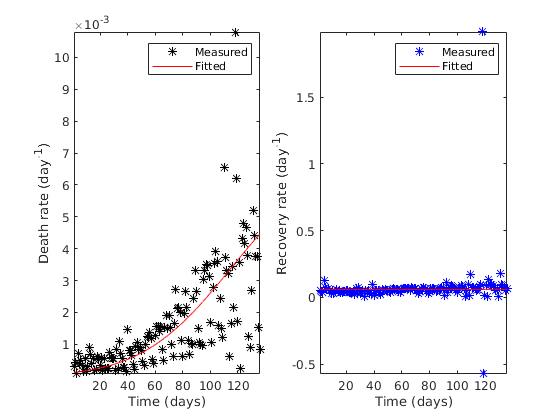

checkRates(time,Active,Recovered,Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

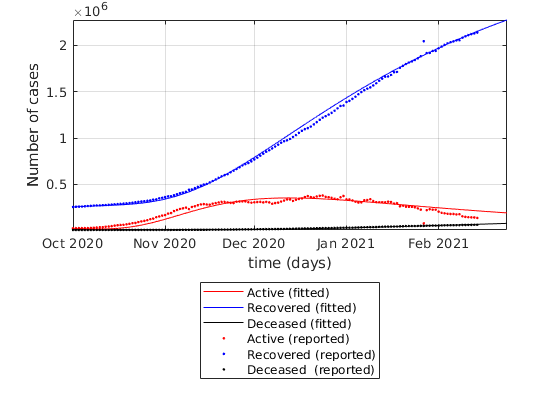

clf;close all;
figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'r.',time,Recovered,'b.',time,Deaths,'k.');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Active (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
 set(gca,'yscale','lin') 